load('D:\Project- Electro\summary - 3-2022\Brain states of Affiliation and Aversive behaviour\Affiliative interaction\video files\ChamberRat26-Probe25-Day4-2021-04-23-215358-0000_video_data_results4.mat')
load('D:\Project- Electro\summary - 3-2022\Brain states of Affiliation and Aversive behaviour\Affiliative interaction\Timestemps\Chamber_Rat26-Probe25-Day4-Behavior_and_Optogenetics_TimeStamps.mat')
load('D:\Project- Electro\summary - 3-2022\Brain states of Affiliation and Aversive behaviour\Affiliative interaction\LFP\Chamber_Rat26-Probe25-Day4-LFP_Data.mat')


time_vec = FramesTimesInSec(1:LastFrameAnalyzed);
time_vec = time_vec - StartTriggerTimeInSec;
probnum = 6;
val = SpikeTimes{probnum};

Undefined variable SpikeTimes.

spike_times = get_clossest_val(time_vec, val);
event_vec = zeros(size(time_vec));
event_vec(spike_times) = 1;
% bin_size_sec = 0.02 ; %sec
% fs = 5000;
% bin_size = round(bin_size_sec*fs);
% [res, time_vec_down] = bin_sum(event_vec,time_vec, bin_size);
% figure;plot(time_vec_down,res)

s1 = StimuliPositionsList{1};
s2 = StimuliPositionsList{2};
% p1 = polyshape(s1(:,2),s1(:,1));
% p2 = polyshape(s2(:,2),s2(:,1));

figure;
% ax1 = subplot(1,2,1);
% imshow(firstFrameInTheAnalysis)
% hold on
% plot(p1)
% plot(p2)
rat_path = MouseLocationCenterOfBody;
numPoints = 20;
[x1,y1] = centroid(p1);
[x2,y2] = centroid(p2);
% x = 317;
% y = 714;
% scatter(x,y)
dist_stim_1 = find_dist(x1,y1,rat_path);
dist_stim_2 = find_dist(x2,y2,rat_path);
dist_stim = dist_stim_1./(dist_stim_1+dist_stim_2);
dist_stim = rescale(dist_stim,0,1);
% dist_stim = fillmissing(dist_stim, "movmedian",10);
% thresh = multithresh(dist_stim,numPoints);
% q = imquantize(dist_stim,thresh);
% 
% 
% cmap = parula(numPoints+1);
% colors = cmap(q,:);
% scatter3(rat_path(:,1), rat_path(:,2),time_vec,5,colors,'filled')

lfp_data = filteredDataLowSummary(probnum,:);
new_fs = 1000;
lfp_data = downsample_audio(lfp_data,5000,new_fs);

lfp_data_times = (0:(numel(lfp_data)-1))/new_fs;
t_stamps_to_keep = lfp_data_times<=time_vec(end);
lfp_data = lfp_data(t_stamps_to_keep);
lfp_data_times = lfp_data_times(t_stamps_to_keep);

figure;
t_range = [200 400];
t_range_inds = get_clossest_val(time_vec, t_range);
inds = (t_range_inds(1):t_range_inds(2));

t_range_inds_lfp = get_clossest_val(lfp_data_times, t_range);
inds_lfp = (t_range_inds_lfp(1):t_range_inds_lfp(2));


[s,f] = cwt(lfp_data(inds_lfp),5000,"FrequencyLimits",[0 100]);
% f_inds = find(f<100);
s = log(abs(s));
t = (0:(size(s,2)-1))/new_fs + t_range(1);

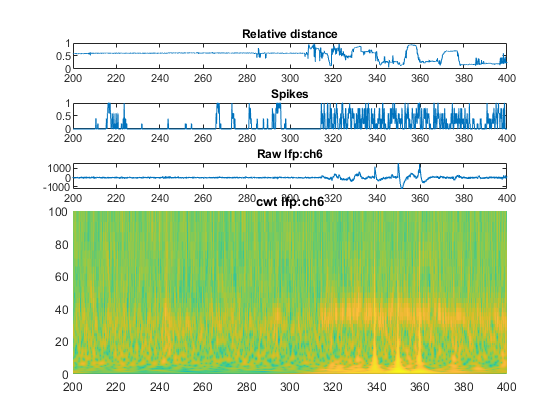

figure;
n_sub = 6;
ax1 = subplot(n_sub,1,1);
plot(time_vec(inds),dist_stim(inds))
title('Relative distance')
ax2 = subplot(n_sub,1,2);
plot(time_vec(inds),smooth(event_vec(inds),5))
title('Spikes')
ax3 = subplot(n_sub,1,3);
plot(lfp_data_times(inds_lfp),lfp_data(inds_lfp))
title(sprintf('Raw lfp:ch%d',probnum))
ax4 = subplot(n_sub,1,4:n_sub);
title(sprintf('cwt lfp:ch%d',probnum))
% [s,f,t,ps] = spectrogram(lfp_data(inds_lfp),256,250,256,5000,'yaxis');

% t = t+t_range(1);
% f_sub = f(f_inds);
% s_sub = s(f_inds,:);
surface(t,f,s,'EdgeColor','none')
linkaxes([ax1,ax2,ax3,ax4],'x')
ax1.XLim = t_range;

function all_inds = get_clossest_val(arr, val)
    n_val = numel(val);
    all_inds = zeros(n_val,1);
    for vali = 1:n_val
        [~,indi] = min(abs(arr-val(vali)));    
        all_inds(vali) = indi;
    end

end
function [res, time_vec_down] = bin_sum(event_vec,time_vec, bin_size)
    n_arr = numel(time_vec);
    n_bins = floor(n_arr/bin_size);
    res = zeros(n_bins,1);
    time_vec_down = zeros(n_bins,1);
    start_ind = 1;
    
    for bini = 1:n_bins
        end_ind = min(start_ind+bin_size,n_arr);
        seg = event_vec(start_ind:end_ind);
        timeseg = time_vec(start_ind:end_ind);
        res(bini) = sum(seg);
        time_vec_down(bini) = mean(timeseg);
        start_ind = min(end_ind+1,n_arr);
    end
end
function dist_out = find_dist(x,y,arr)
    dist_out = pdist2(arr,[x,y]);
%     dist_out = fillmissing(dist_out,"movmean",10);
    dist_out = filloutliers(dist_out,"nearest");
end